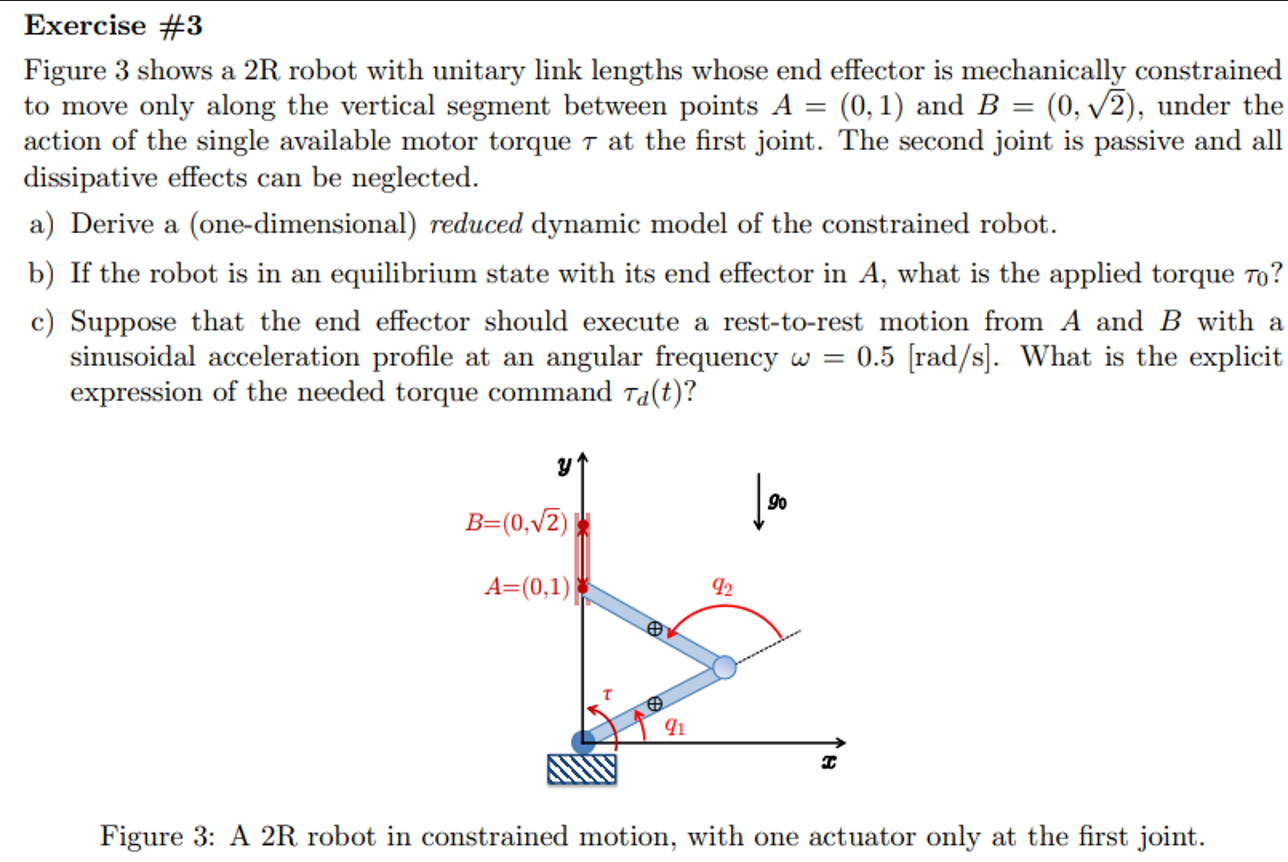

syms q1 q2 q3 q_dot_1 q_dot_2 q_dot_3 real
syms d_1 d_2 l_1 m_1 m_2 m_3 I_1 I_2 l_2 g0 positive
syms a1 a2 a3 positive

% Dynamic model
% joint 1 
x1 = d_1*cos(q1);
y1 = d_1*sin(q1);

vx1 = diff(x1,q1)*q_dot_1 + diff(x1,q2)*q_dot_2;
vy1 = diff(y1,q1)*q_dot_1 + diff(y1,q2)*q_dot_2;

T1_tr = 0.5*m_1*[vx1 vy1]*[vx1; vy1;];
T1_rot = 0.5*I_1*[0 0 q_dot_1]*[0; 0; q_dot_1;];
T1 = T1_tr+T1_rot

$$T1 = \frac{m_{1}\,{d_{1}}^{2}\,{{\dot{q}}_{1}}^{2}\,{\cos\left(q_{1}\right)}^{2}}{2}+\frac{m_{1}\,{d_{1}}^{2}\,{{\dot{q}}_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}}{2}+\frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$


% joint 2 
x2 = l_1*cos(q1) + d_2*cos(q1+q2);
y2 = l_1*sin(q1) + d_2*sin(q1+q2);

vx2 = diff(x2,q1)*q_dot_1 + diff(x2,q2)*q_dot_2;
vy2 = diff(y2,q1)*q_dot_1 + diff(y2,q2)*q_dot_2;

T2_tr = 0.5*m_2*[vx2 vy2]*[vx2; vy2;];
T2_rot = 0.5*I_2*[0 0 q_dot_1+q_dot_2]*[0; 0; q_dot_1+q_dot_2;];
T2 = T2_tr + T2_rot

$$T2 = \frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(d_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)+d_{2}\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(d_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)+d_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)\right)}^{2}}{2}$$


% Total Energy
T = T1+T2

$$T = \frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(d_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)+d_{2}\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(d_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)+d_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)\right)}^{2}}{2}+\frac{{d_{1}}^{2}\,m_{1}\,{{\dot{q}}_{1}}^{2}\,{\cos\left(q_{1}\right)}^{2}}{2}+\frac{{d_{1}}^{2}\,m_{1}\,{{\dot{q}}_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}}{2}$$


% Inertia Matrix
M11 = diff(diff(T, q_dot_1), q_dot_1);
M12 = diff(diff(T, q_dot_1), q_dot_2);

M21 = diff(diff(T, q_dot_2), q_dot_1);
M22 = diff(diff(T, q_dot_2), q_dot_2);

M = [M11, M12;
     M21, M22;];
M = simplify(M)

$$M = \left(\begin{array}{cc} m_{1}\,{d_{1}}^{2}+m_{2}\,{d_{2}}^{2}+2\,m_{2}\,\cos\left(q_{2}\right)\,d_{2}\,l_{1}+m_{2}\,{l_{1}}^{2}+I_{1}+I_{2} & m_{2}\,{d_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,d_{2}+I_{2}\\ m_{2}\,{d_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,d_{2}+I_{2} & m_{2}\,{d_{2}}^{2}+I_{2} \end{array}\right)$$


% Parametrization of M
M_para =[a1+2*a2 a3+a2;
    a3+a2 a3;];

% Coriolis and Centrifugal force
q  = [q1; q2;];
dq = [q_dot_1; q_dot_2;];
C = sym(zeros(2,2));

for i = 1:2
    for j = 1:2
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} -d_{2}\,l_{1}\,m_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right) & -d_{2}\,l_{1}\,m_{2}\,\sin\left(q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ d_{2}\,l_{1}\,m_{2}\,{\dot{q}}_{1}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -d_{2}\,l_{1}\,m_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\,\left(2\,{\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ d_{2}\,l_{1}\,m_{2}\,{{\dot{q}}_{1}}^{2}\,\sin\left(q_{2}\right) \end{array}\right)$$


% Gravity Terms
U1 = m_1*g0*(d_1*sin(q1))

$$U1 = d_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$

U2 = m_2*g0*(d_2*sin(q1+q2))

$$U2 = d_{2}\,g_{0}\,m_{2}\,\sin\left(q_{1}+q_{2}\right)$$


U = [U1+U2];
g_q = simplify([diff(U,q1); diff(U,q2);], Steps=100)

$$g\_q = \left(\begin{array}{c} d_{2}\,g_{0}\,m_{2}\,\cos\left(q_{1}+q_{2}\right)+d_{1}\,g_{0}\,m_{1}\,\cos\left(q_{1}\right)\\ d_{2}\,g_{0}\,m_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$